x = -5:0.1:5;
y = -5:0.1:5;
[x,y] = meshgrid(x,y);
z = 20+(x.^2-10*cos(2*pi.*x)) + (y.^2-10*cos(2*pi.*y));
surf(x,y,z)
hold on



xn = 2;
yn = 2;
zn = 20+(xn^2-10*cos(2*pi*xn)) + (yn^2-10*cos(2*pi*yn));
alpha = 0.001;

for ii = 1:100
    dzx = 2*xn +20*pi*sin(2*pi*xn);
    dzy = 2*yn +20*pi*sin(2*pi*yn);

    xn = xn - alpha*dzx;
    yn = yn - alpha*dzy;
    zn = 20+(xn^2-10*cos(2*pi*xn)) + (yn^2-10*cos(2*pi*yn));
end
xn 

xn = 1.9899

yn

yn = 1.9899

zn

zn = 7.9597

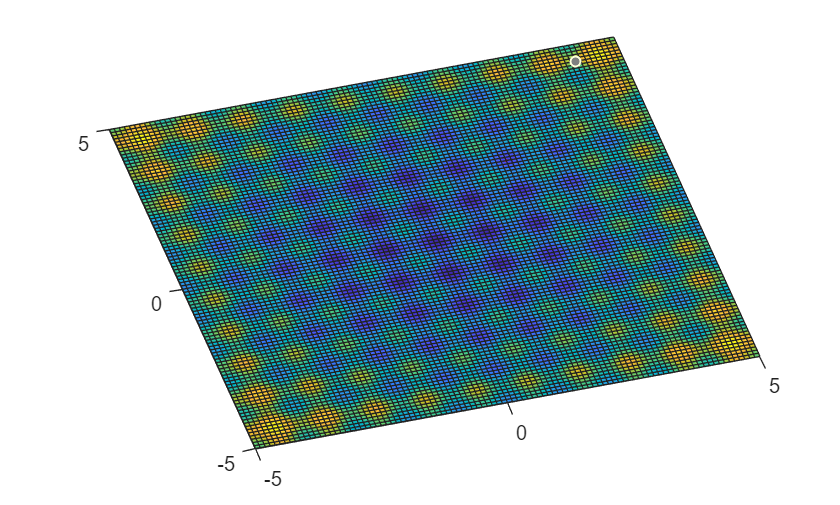

plot3(xn,yn,zn,'.','Markersize',20,'Color','r')
hold off